# Connected Greenhouse

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

In this script, you will design the control algorithm for a greenhouse. The system relies on a fan blowing fresh air from the outside to cool down the inside of the greenhouse during the warmer months of the year.

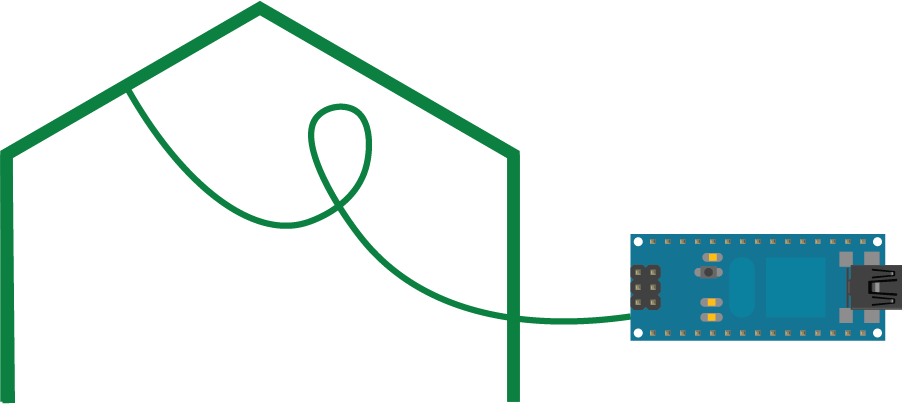

This image was created in part using [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

**Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

The Internet of Things (IoT) refers to the network of interconnected devices, objects, and systems that can communicate and exchange data over the Internet. It enables everyday objects like appliances, vehicles, and wearable devices to connect and interact, creating a seamless and intelligent network of physical objects. IoT has the potential to revolutionize various industries by enabling data-driven decision-making, automation, and enhanced connectivity, ultimately leading to increased efficiency, convenience, and innovation in our daily lives.

## Background

In the previous scripts ([GreenhouseControl.mlx](matlab:open('./GreenhouseControl.mlx')) & [GreenhouseModel.mlx](matlab:open('./GreenhouseModel.mlx'))), we developed a temperature-controlled greenhouse. A DHT sensor is used to measure the temperature inside the greenhouse, and a fan is in charge of bringing fresh air if the temperature 

## Thingspeak

Thingspeak is an IoT platform developed by MathWorks. It provides a convenient and easy-to-use interface for collecting, analyzing, and visualizing data from your IoT devices. With ThingSpeak, users can create IoT applications and projects by integrating sensors, actuators, and other devices and monitor and control them remotely. It also offers features like data logging, real-time data visualization, and the ability to trigger actions based on specific conditions, making it a versatile platform for building IoT solutions.

We will leverage ThingSpeak with our Arduino board to send an alert when the Greenhouse temperature exceeds a certain temperature.

Before starting the greenhouse, we should explore some of ThingSpeak's functionality. 

### Collect data from a public channel

In ThingSpeak, all of the data are stored on a **channel.** In general, each connected device will use its own channel. Larger projects might require multiple channels. Like social media profiles or video content shared online, your channel can be public or private. Public channels allow you to share the data with anyone, while private channels require you to share access with another user if you want to share.

In [GreenhouseModel](matlab:open('./GreenhouseModel.mlx')), we used weather data from a weather station in Natick, MA. This weather station was developed by MathWorks staff, and all of its data is available on a ThingSpeak public channel.

  **Try.** Visit the channel page to familiarize yourself with the user interface.

web("https://thingspeak.com/channels/12397")
 

 **Exercise.** What kind of data is stored on this channel?

DataOnChannel( ...
false,false,false,false,false,false,false,false,false);
 


### Create your private channel

Now that you understand the data that can be stored on a ThingSpeak channel, you should try creating your own. Before getting started, return to the ThingSpeak [website](https://thingspeak.com/) and connect to your account.

- In the top menu, click **Channels > My Channels**

- Click **New Channel**

- Name your channel:** MyFirstChannel**

- Name the first field:** TestData**

 **Exercise.** Scroll down and click the **Save Channel** button. Switch the view to the **API Keys **tab and copy the keys in the following edit field

ChannelID = [ ];
WriteAPIKey = "";
ReadAPIKey = "";
 
CheckChannelCreated(ChannelID,WriteAPIKey,ReadAPIKey)

### **Send data to a channel**

After successfully creating your first ThingSpeak channel, the next step is to generate an artificial signal to be transmitted to the channel. This signal can be simulated or generated using various methods, such as mathematical functions or predefined patterns. By sending this artificial signal to the channel, you can test and analyze the functionality of your IoT devices and applications, ensuring they are properly integrated and capable of transmitting and receiving data.

  **Try. **Click the following button to generate a sinusoidal signal

 
y = sin(linspace(0,2*pi,30));
t0 = datetime('now')-seconds(30);
t1 = t0+seconds(30);
ts = linspace(t0,t1,30);
plot(ts,y)
xlim([t0 t1])

Now that the signal has been created, it's time to transmit or send it to the desired channel. This can be achieved using the thingSpeakWrite function in MATLAB. Note that sending data to the channel is commonly referred to as writing data, hence the function's name.

  **Try. **Send the signal to the ThingSpeak channel

 
try
    thingSpeakWrite(ChannelID,timetable(ts',y',VariableNames="Test"),"WriteKey",WriteAPIKey)
    disp("Data was succesfully sent.")
catch
    warning("An error occured, try again or restart from the top.")
end

With the successful data transmission, it's time to visualize the results on the private view of the ThingSpeak channel. Note that the data might take a few minutes to show on this web page.

  **Try. **Check the online visualization.

if ChannelID ~= []
    web("https://thingspeak.com/channels/"+ChannelID+"/private_show")
end
 

## **IoT with Arduino**

Having accomplished the creation of our channel, writing data to it, and visualizing the data online using an artificial signal generated in MATLAB, the next step is to explore the integration of real-world data by utilizing an Arduino. By connecting an Arduino to our ThingSpeak channel, we can collect and transmit data from physical sensors or devices.

The easiest way to connect an Arduino board to the internet and control it with MATLAB and Simulink is to get an Arduino board with native WiFi support. The following boards have native WiFi support and are supported by the MATLAB and Arduino support packages:

- Arduino Nano 33 IoT

- Arduino MKR WiFi

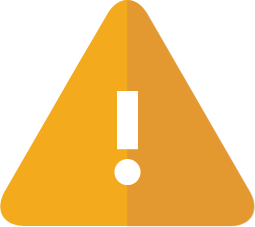  The rest of this script considers that you are using one of these two boards.

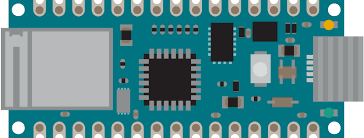               

Representation of an Arduino Nano IoT board - Image was created using [fritzing-parts](https://github.com/fritzing/fritzing-parts/)    

### Set the WiFi Connection

To use the ThingSpeak block in Simulink, we need to set the WiFi connection in the Simulink Model. 

  Check that your Arduino board is connected to your computer.

  **Try. **Open the model

open(fullfile("Models","ConnectedGreenhouse.slx"))
 

  **Try. **Follow these step-by-step instructions to set the board and WiFi settings

- Go to the **MODELING** tab

- Open **Model Settings**

- In **Hardware Implementation**, select **Arduino Nano IoT** or** Arduino MKR WiFI** in the **Hardware Board setting**

- Expand the **Target hardware resources**

- In **WiFi properties**, inform the **SSID** and WiFI **encryption** accordingly.

   Arduino board only supports WiFi networks at 2.3 GHz. You cannot connect the board to your network if your WiFi is 5G (5 GHz).

 **Exercise.** Add the Channel ID and Write API key to the Thingspeak Write block

 CheckThingSpeakBlock(ChannelID,WriteAPIKey)

 **Exercise.** Connect the DHT's Temperature port to the ThingSpeak Write.

 CheckDHTtoThingSpeak

  **Try. **Click the **Build, Deploy & Start **button in the **HARDWARE** tab of the Simulink Toolstrip.

  **Try. **Check the visualization online, the channel should be updated with the temperature read by the sensor every minute.

if ChannelID ~= []
    web("https://thingspeak.com/channels/"+ChannelID+"/private_show")
end
 

### Create Alert

We now have a ThingSpeak channel registering the temperature every minute. We are going to create an alert if the temperature exceeds 90 F. 

#### Set up the alert API key

  **Try. **Open your ThingSpeak profile

web("https://thingspeak.com/account/profile")
 

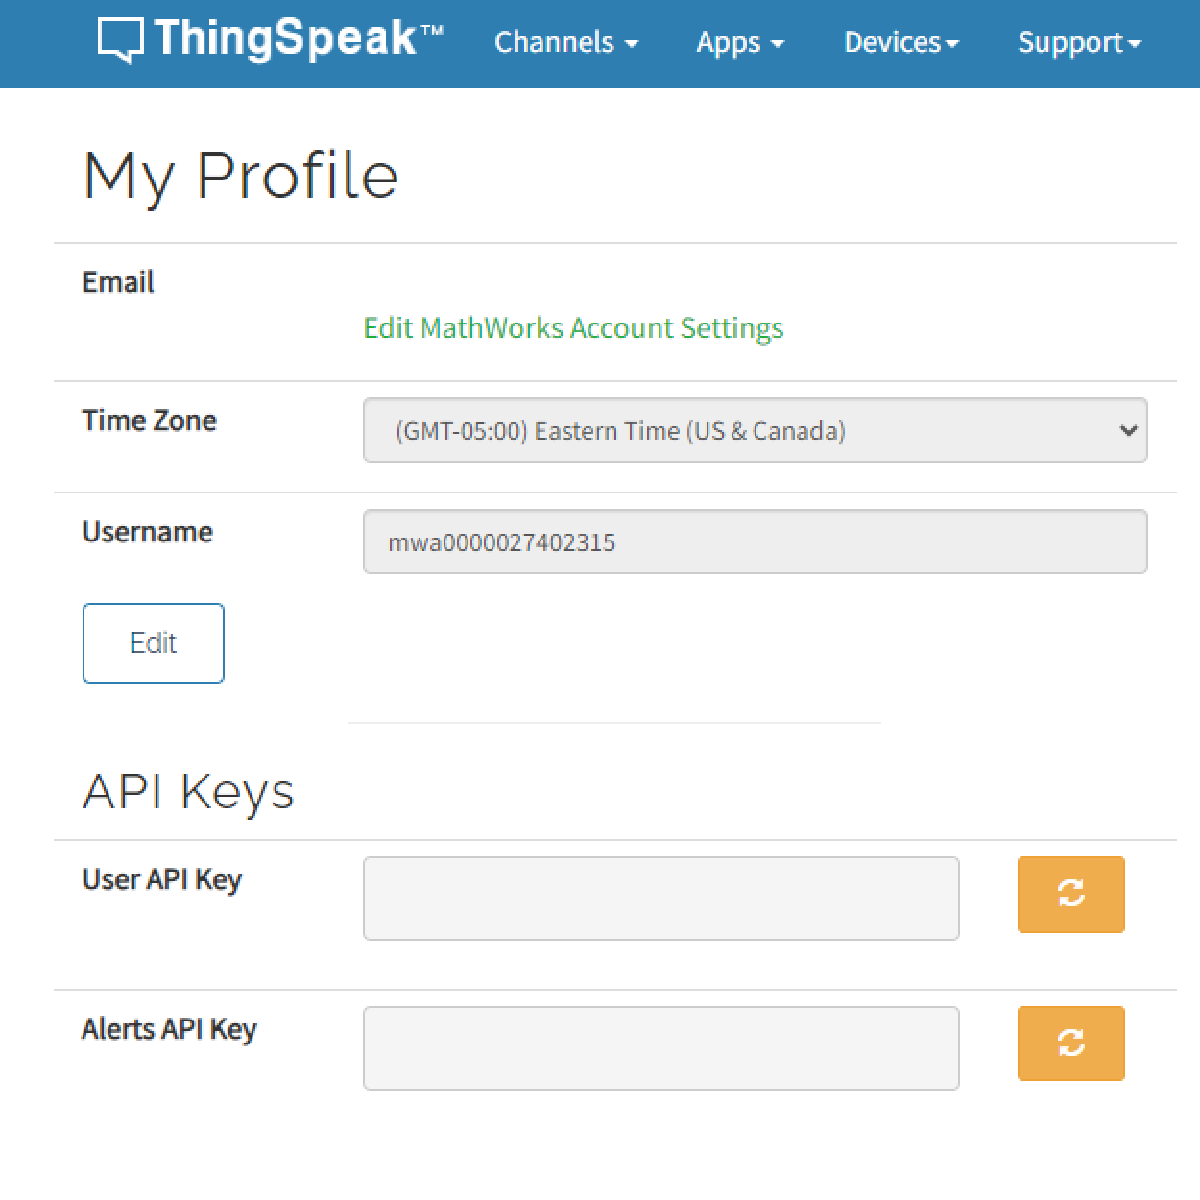

 **Exercise. **Generate an Alert API Key and add it to the following edit field.

AlertAPIKey = "";

#### Set the HTTP request to send alerts

Now that you have an Alert API Key, your ThingSpeak account can send alerts. The first step in generating an alert is to pre-defined the message sent when the alert is triggered. This message will be transmitted through a ThingHTTP

  **Try. **Open the ThingHTTP setting page and click New ThingHTTP.

web("https://thingspeak.com/apps/thinghttp")
 

 **Exercise. **In the new alert dialog, modify all the following parameter

**Name:** Send Temperature Alert

**URL:** https://api.thingspeak.com/alerts/send

**Method:** POST

**Headers:** Create two headers

**Body: **Copy the code provided in the following code example box.

   Don't forget to set your Alert before continuing.

#### Enable Channel React

In the previous section, we created a ThingHTTP request that, when triggered, should send an alert email to the channel owner (you). In this section, we are going to create a ThingSpeak React. ThingSpeak React is a triggering mechanism that can be programmed to complete an action, such as the ThingHTTP we programmed earlier.

  **Try. **Open the React settings page and click New React.

web("https://thingspeak.com/apps/reacts")
 

 **Exercise. **In the new React dialog, modify all the following parameters

**Name:** Temperature Alert Trigger

**Condition Type:** numeric

**Test Frequency:** On Data Insertion

**Condition: **

    If Channel: MyFirstChannel

    field: 1 (TestData)

    is greater than

    90

**Action:** ThingHTTP

    Send Temperature Alert

**Options:** Run action only the first time the condition is met

   Don't forget to set your React before continuing.

#### Test the alert

In this section, we are testing the alert that we just created. We will send a fake data point to the ThingSpeak channel manually. The temperature sent to the channel is 95 F, which exceeds the 90 F limit we are imposing and should immediately trigger an email. 

  **Try. **Test the alert by manually sending fake data to the channel

if ChannelID ~= []
    thingSpeakWrite(ChannelID,95,"WriteKey",WriteAPIKey)
end
 

## Conclusion

In this script, you learned how:

- To read and write data to an online service/IoT Cloud Platform (ThingSpeak) via MATLAB and Simulink. 

- To visualize data online.

- create a triggering mechanism and send alerts based on the recorded data.

## Further exploration

If you want to learn more about visualization and recording of more data, the MathWorks Internet of Things team [published the design guide from a weather station](https://www.mathworks.com/matlabcentral/fileexchange/47049-analyzing-weather-data-from-an-arduino-based-weather-station) they developed at MathWorks campus.

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Helper Functions

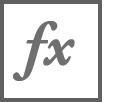`CheckChannelCreated`

function CheckChannelCreated(ChannelID,~,ReadAPIKey)
    
    err = false;

    if isempty(ChannelID)
        warning("Please complete the channel ID.")
        err = true;
    end
    
    try
        [~,channelInfo] = thingSpeakRead(ChannelID,ReadKey=ReadAPIKey,OutputFormat="table");
        if string(channelInfo.Name) ~= "MyFirstChannel"
        err = true;
        warning("The name of your first channel should be MyFirstChannel.")
        end
        if string(channelInfo.FieldDescriptions{1}) ~= "TestData"
            err = true;
            warning("The first channel description should be 'Test'.")
        end
    catch
        err = true;
        warning("Could connect to your newly created channel, make sure that the ChannelID, Write API key and Read API key are correct.")
    end
    
    
    if ~err
        disp("Good job! You created your first ThingSpeak channel correctly.")
    end 
end

`DataOnChannel`

function DataOnChannel(a1,a2,a3,a4,a5,a6,a7,a8,a9)
    answer = [a1,a2,a3,a4,a5,a6,a7,a8,a9];
    if all(answer)
        disp("Good job! You found all the data registered on this channel.")
    else
        warning("You are missing some of the data registered on the channel")
    end
end

`CheckThingSpeakBlock`

function CheckThingSpeakBlock(ChannelID,WriteAPIKey)
    load_system(fullfile("Models","ConnectedGreenhouse"))
    err = false;
    SymChannelID = double(string(get_param("ConnectedGreenhouse/WiFi ThingSpeak Write","ChannelID_")));
    SymWriteAPI = string(get_param("ConnectedGreenhouse/WiFi ThingSpeak Write","WriteAPIKey_"));
    if SymChannelID ~= ChannelID
        err = true;
        warning("The channel ID in the ThingSpeak Write does not match the channel that you just created.")
    end
    if SymWriteAPI ~= WriteAPIKey
        err = true;
        warning("The Write API key in the ThingSpeak Write does not match the one from the channel you just created.")
    end
    if ~err
        disp("Good job! The ThingSpeak Write block is configured correctly.")
    end
end

`CheckDHTtoThingSpeak`

function CheckDHTtoThingSpeak()
    load_system(fullfile("Models","ConnectedGreenhouse"))
    conn = get_param("ConnectedGreenhouse/DHT","PortConnectivity");
    if isempty(conn(2).DstBlock)
        warning("You need to connect the T port from the DHT sensor to the Thinsgpeak Block")
    else
        disp("Good job! The block is connected correctly.")
    end
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Copyright 2023 The MathWorks™, Inc